M values:
     4     6     8    10

W values:
    10    12    14    16    18    20    22    24

W=10.0000, M=4
W=10.0000, M=6
W=10.0000, M=8
W=10.0000, M=10
W=12.0000, M=4
W=12.0000, M=6
W=12.0000, M=8
W=12.0000, M=10
W=14.0000, M=4
W=14.0000, M=6
W=14.0000, M=8
W=14.0000, M=10
W=16.0000, M=4
W=16.0000, M=6
W=16.0000, M=8
W=16.0000, M=10
W=18.0000, M=4
W=18.0000, M=6
W=18.0000, M=8
W=18.0000, M=10
W=20.0000, M=4
W=20.0000, M=6
W=20.0000, M=8
W=20.0000, M=10
W=22.0000, M=4
W=22.0000, M=6
W=22.0000, M=8
W=22.0000, M=10
W=24.0000, M=4
W=24.0000, M=6
W=24.0000, M=8
W=24.0000, M=10


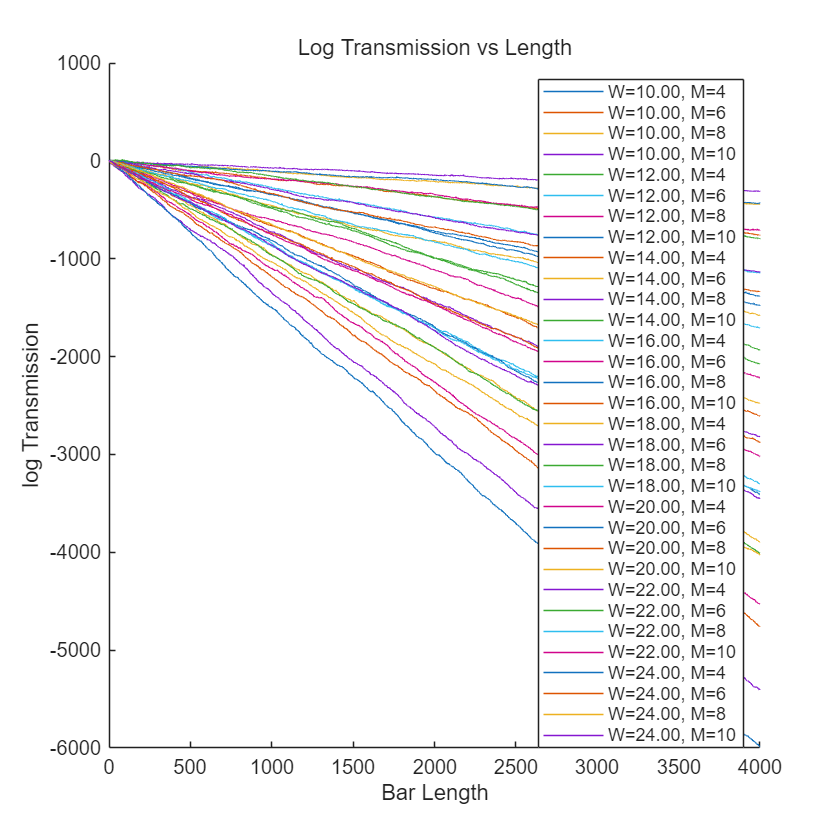

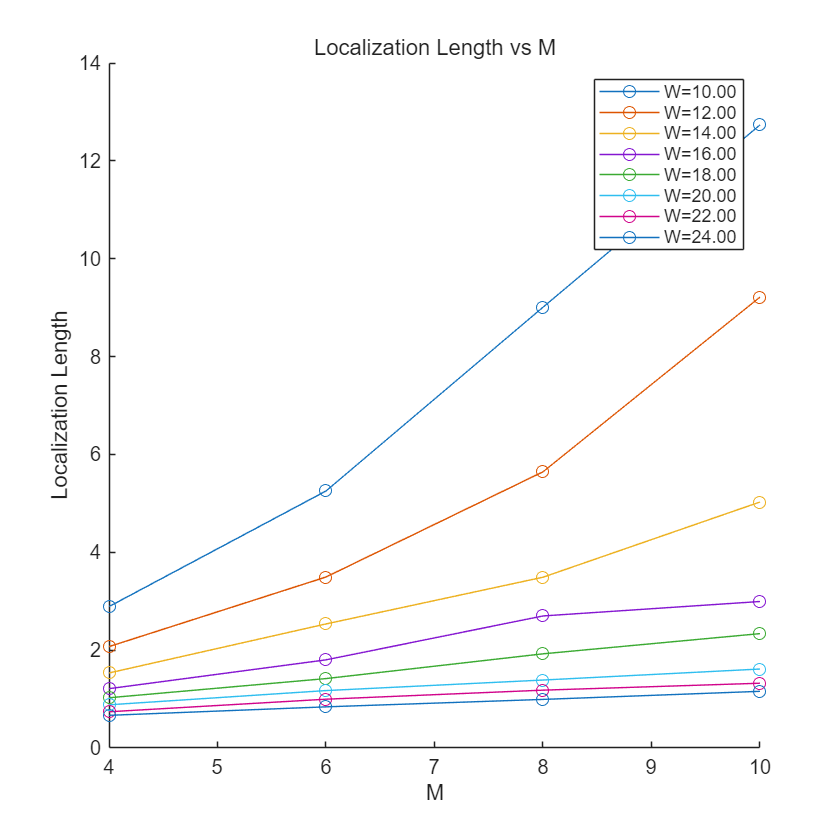

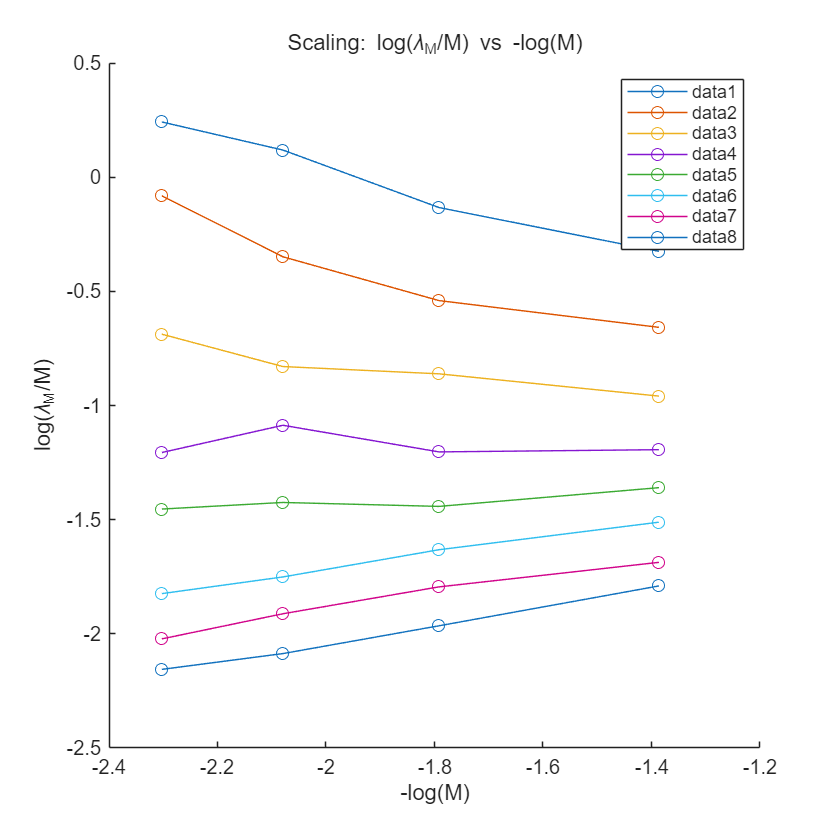

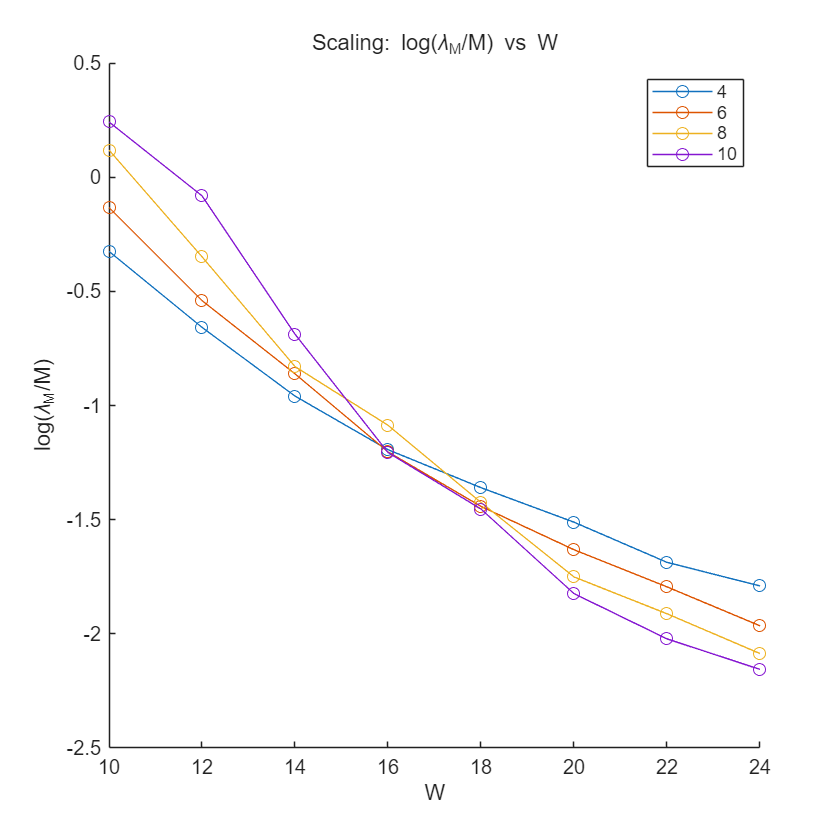

clear
transmission_anderson_model_3d(4000, 4, 10, 4, 10, 24, 7, 0);


% tic;
% energy = 0:1:8;
% Wc_E = zeros(2*length(energy), 1);
% Count = 1;
% energy_Wc = zeros(2*length(energy), 1);
% for ii = 1:length(energy)
%     Wc_temp = transmission_anderson_model_3d(10000, 4, 12, 2, 1, 21, 21, energy(ii));
%     disp(Wc_temp)
%     if length(Wc_temp)>1
%         Wc_E(Count) = Wc_temp(1);
%         energy_Wc(Count) = energy(ii);
%         Wc_E(Count+1) = Wc_temp(2);
%         energy_Wc(Count+1) = energy(ii);
%         Count = Count + 2;
%     else
%         Wc_E(Count) = Wc_temp;
%         energy_Wc(Count) = energy(ii);
%         Count = Count + 1;
%     end
% end
% ind = find(Wc_E);
% % energy_Wc = nonzeros(energy_Wc);
% 
% plot(energy_Wc(ind), Wc_E(ind)/Wc_E(1),'o')
% toc;


function Wc = transmission_anderson_model_3d(L, M_min, M_max, M_nsteps, W_min, W_max, W_nsteps, energy)
    tab_M = round(linspace(M_min, M_max, M_nsteps));
    tab_W = linspace(W_min, W_max, W_nsteps+1);
    disp("M values:"); disp(tab_M);
    disp("W values:"); disp(tab_W);

    tab_localization_length = zeros(W_nsteps+1, M_nsteps);

    for i_W = 1:W_nsteps+1
        W = tab_W(i_W);
        for i_M = 1:M_nsteps
            M = tab_M(i_M);
            fprintf("W=%.4f, M=%d\n", W, M);
            [loc_len, tab_trans] = compute_localization_length(L, M, W, energy);
            tab_localization_length(i_W, i_M) = loc_len;

            % 作图：每次传输的 log 值
            figure(1); hold on;
            plot(0:L, tab_trans, 'DisplayName', sprintf('W=%.2f, M=%d', W, M));
        end
    end
    hold off;
    xlabel('Bar Length');
    ylabel('log Transmission');
    title('Log Transmission vs Length');
    legend show;

    % 作图：localization length vs M (每个 W)
    figure; hold on;
    for i_W = 1:W_nsteps+1
        plot(tab_M, tab_localization_length(i_W, :), '-o', 'DisplayName', sprintf('W=%.2f', tab_W(i_W)));
    end
    hold off;
    xlabel('M');
    ylabel('Localization Length');
    title('Localization Length vs M');
    legend show;

    % 作图：scaling_M (log-log)
    figure; hold on;

    log_scaling = log(tab_localization_length ./ tab_M);
    plot(-log(tab_M), log_scaling, '-o');

    hold off;
    xlabel('-log(M)');
    ylabel('log(\lambda_M/M)');
    title('Scaling: log(\lambda_M/M) vs -log(M)');
    legend show;

    % 作图：scaling_W
    figure; hold on;
    log_scaling = log(tab_localization_length ./ tab_M);
    % log_scaling = tab_localization_length ./ tab_M;
    plot(tab_W, log_scaling, '-o');
    hold off;
    xlabel('W');
    ylabel('log(\lambda_M/M)');
    title('Scaling: log(\lambda_M/M) vs W');
    leg = arrayfun(@(x) num2str(x), tab_M, 'UniformOutput',false);
    legend(leg);
    % diff_vec = diff(log_scaling,1,2);
    % Wc = tab_W(find(diff(diff_vec>=0),2));
end

function [localization_length, tab_trans] = compute_localization_length(L, M, W, energy)
    % potential = generate_disorder(M, L+1, W);
    dim_tab_trans = L+1;
    tab_trans = zeros(1, dim_tab_trans);
    g1n = eye(M*M) / sqrt(M*M);
    gnn = zeros(M*M, M*M);
    H00 = full(get_Nearest_Square_Hopping_Sparse_V2(M, M, 1, 1));
    x = 0;
    for i = 1:L+1
        gnn = energy*eye(M^2) - gnn - H00 - W * diag(rand(M^2,1) - 0.5);
        % gnn = -gnn;
        gnn = inv(gnn);
        scratch = g1n * gnn;
        small_b = norm(scratch, 'fro');
        x = x + 2 * log(small_b);
        g1n = scratch / small_b;
        tab_trans(i) = x;
    end
    localization_length = L / (tab_trans(1) - tab_trans(end));
end